# Intro to Computational Imaging (ci) Classes

ciCamera is one of a set of classes that allow experimentation with computational imaging more directly than the previous "lower-level" scene, oi, sensor, and ip structs. Along with ciScene, ciCModule, and ciIP, it provides a programmable wrapper that allows users to create "cameras" that have a variety of algorithms for deciding how to capture a scene, and then how to process one or more captures, potentially even from more than one camera module (ciCModule).

History: Initial Version: D. Cardinal 12/2020

ieInit();
% ciBurstCamera is a sub-class that implements simple HDR and Burst
% capture and processing
ourCamera = ciBurstCamera(); 
% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('NikonD100Sensor');
ourCamera.cmodule = ciCModule('sensor', sensor); % default

Now we define our scene. The Cornell Box + Bunny is part of iset3d, and is set up to help us by labeling the assets in such a way that we can add motion to them:

scenePath = 'Cornell_BoxBunnyChart';        
sceneName = 'cornell box bunny chart';
ourScene = ciScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'numRays', 32, 'lensFile','dgauss.22deg.50.0mm.json');

Read 11 materials
Read 3 textures
Reading C4D geometry information.


This sets the Stanford bunny in motion with a vertical movement and a tiny rotation. The camera is also set in motion:

% Move the bunny up, with slow rotation
ourScene.objectMotion = {{'Default_B', [0, 15, 0], [1, 1, 1]}};

For the simplest case we ask our camera to take a picture. By deault it uses the 'Auto' intent. Using 'Burst' will capture more frames if the camera type we are using supports it. 'HDR' will also fire a burst, but bracketed.

New light added.
Reading multispectral data with raw data.
New light added.
Reading multispectral data with raw data.


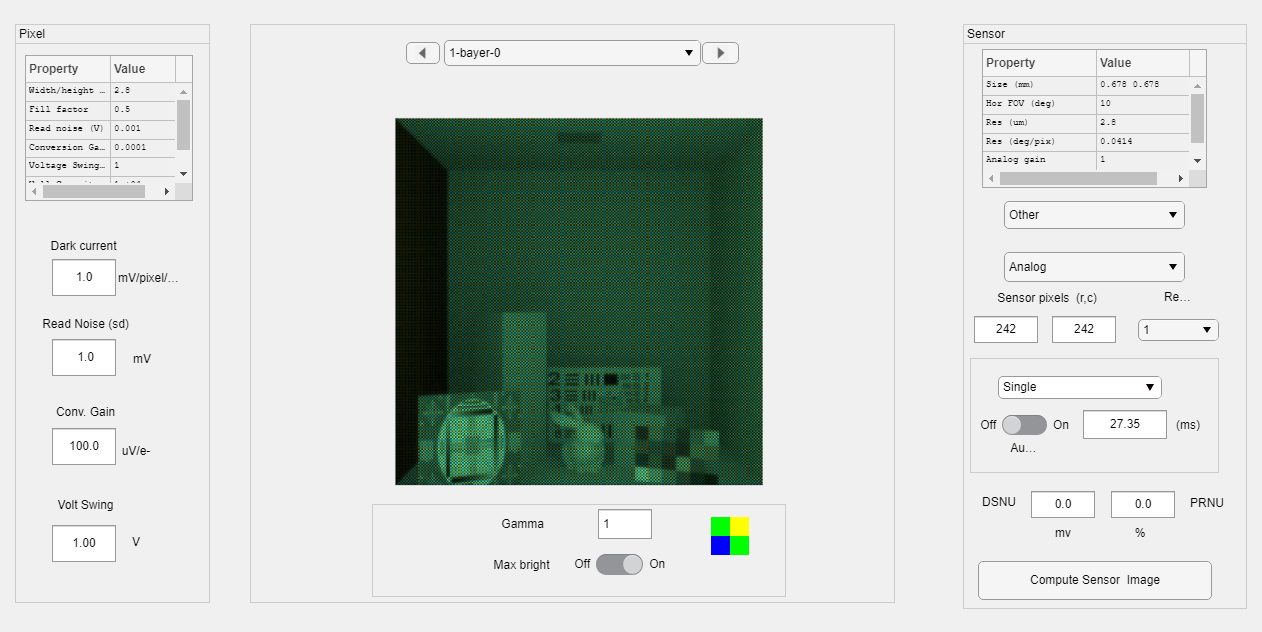

autoImage = ourCamera.TakePicture(ourScene, 'Auto','imageName','Auto Mode');

ieAddObject(autoImage); 
hdrImage = ourCamera.TakePicture(ourScene, 'HDR', 'numHDRFrames', 3,'imageName','HDR Example');

New light added.
Reading multispectral data with raw data.
New light added.
Reading multispectral data with raw data.
Reading multispectral data with raw data.
Reading multispectral data with raw data.


ieAddObject(hdrImage); 
burstImage = ourCamera.TakePicture(ourScene, 'Burst', 'numBurstFrames', 3, 'imageName','Burst Example');

New light added.
Reading multispectral data with raw data.
New light added.
Reading multispectral data with raw data.
Reading multispectral data with raw data.
Reading multispectral data with raw data.


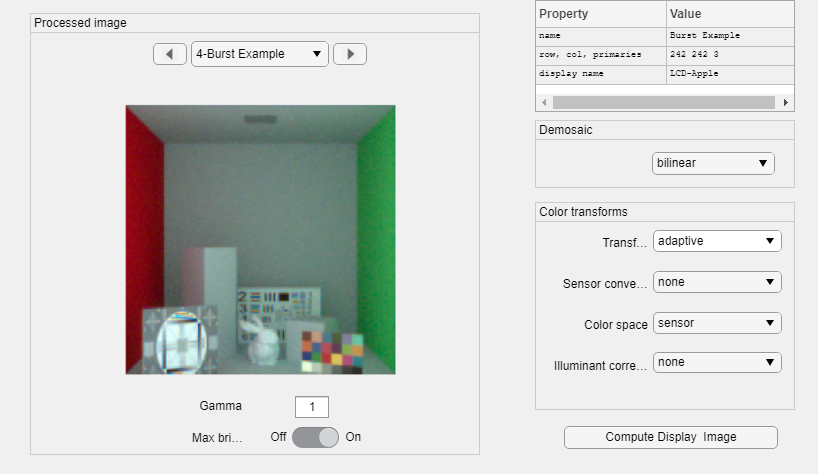

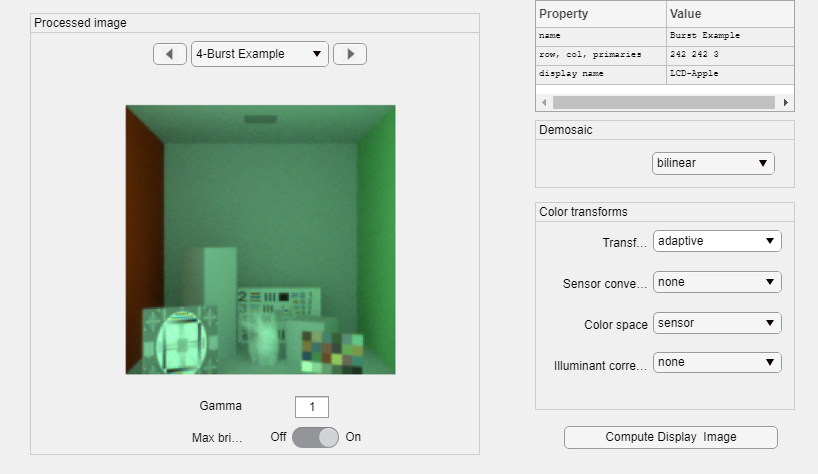

ieAddObject(burstImage); 
ipWindow(); % show the results

% Need to clear scene cache if we want to add camera motion...
% Rotate the camera between frames
% Note that we don't have a way to move the camera during frames (yet)
%ourScene.cameraMotion = {{'unused', [0, 0, 0], [2, 2, 2]}};
% now see what the burst looks like with the camera rotating
%finalImage = ourCamera.TakePicture(ourScene, 'Burst', 'numBurstFrames', 3);
%ipWindow(finalImage); % show the result of a burst of images